# Autómata de Wolfram - Instrucciones

**Juan Uriel Legaria Peña**

**Inteligencia Artificial**

**Maestria en Ciencia e Ingenieria de la Computación **

La implementación consta de 3 clases:

* RuleGenerator *se usa para generar reglas predefinidas que en la literatura se ha visto dan resultados interesantes. Las que se tienen hasta el momento son reglas 90, 60 y 30. 

Cada regla viene representada como un arreglo de 8 entradas, donde cada una de las entradas describe la salida para un vecindario dado. Por ejemplo, si los vecinos a la derecha e izquierda son iguales a uno y la celda del centro tiene valor igual a 0 (vecindario de la forma 101), entonces la salida correspondiente se encontraria en la entrada $2^{\left\lbrace 2\right\rbrace } \times 1+2^{\left\lbrace 1\right\rbrace } \times 0+2^{\left\lbrace 0\right\rbrace } \times 1\;+1=6$ de la regla. Es decir, pasando a decimal la representación binaria del vecindario podemos encontrar el indice de la regla en la cual se encuentra la salida requerida.

 *WolframAutomaton *es la clase del automata, para inicializarlo debemos darle una regla que usará para evolucionar al sistema y también un nombre, que se pasa al constructor como una cadena. Este último sirve sobre todo como un identificador del automata, y para usarlo dentro del título de las gráficas a realizar. 

*WolframAutomatonRenderer *se utiliza para visualizar la evolución del autómata. Su inicialización requiere un objeto de tipo WolframAutomaton. El método a usar para desplegar la evolución del automata es *renderAutomaton, *el cual toma como argumente unicamente el número de pasos deseados.

## **Ejemplos de uso para generar los gráficos de las distintas reglas. **

### Regla 90 (Sierpinski)

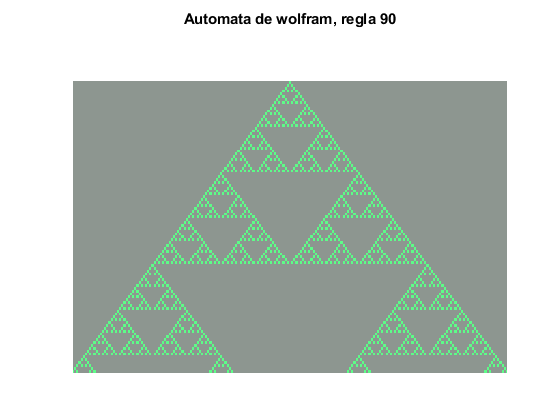

%Establecemos el tipo de regla que queremos
ruleType = RuleType.RULE_90;
%Generamos la regla usando la clase RuleGenerator
rule = RuleGenerator().getRule(ruleType);
%Creamos un automata con la regla, el segundo parámetro es el nombre de la
%regla dado como string, este será el que aparecera en el nombre de la grafica cuando 
% la creemos. 
automaton90 = WolframAutomaton(rule,"90");
%Creamos el renderizador de automatas. 
automaton90Renderer = WolframAutomatonRenderer(automaton90);
%Dibujamos la evolución 
steps = 100;
img = automaton90Renderer.renderAutomaton(steps);

### Regla 60

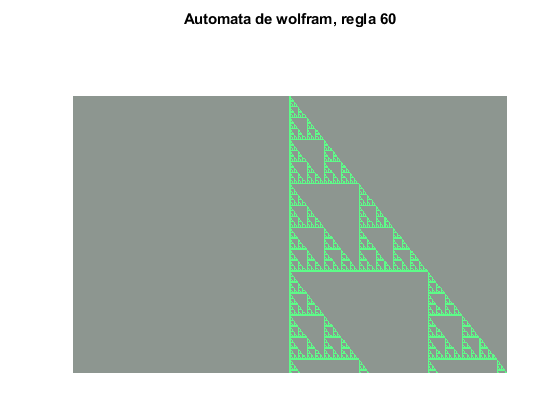

%Establecemos el tipo de regla
ruleType = RuleType.RULE_60;
%Generamos la regla
rule = RuleGenerator().getRule(ruleType);
%Inicializamos el automata pasando la regla como argumento
automaton60 = WolframAutomaton(rule,"60");
%Evolucionamos y graficamos el automata usando la clase
%WolframAutomatonRenderer
automaton60Renderer = WolframAutomatonRenderer(automaton60);
steps = 200;
img = automaton60Renderer.renderAutomaton(steps);

### Regla 30 (caos)

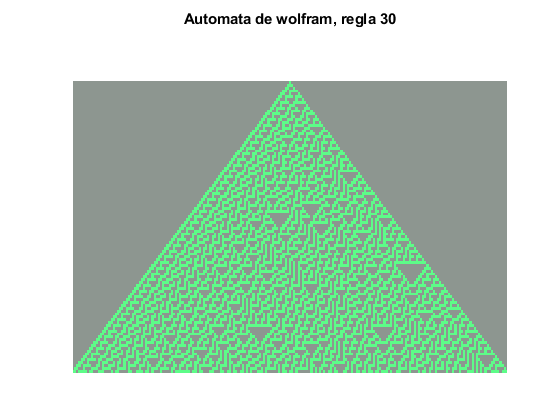

%Establecemos el tipo de regla
ruleType = RuleType.RULE_30;
%Generamos la regla
rule = RuleGenerator().getRule(ruleType);
%Creamos el automata
automaton30 = WolframAutomaton(rule,"30");
%Evolucionamos y visualizamos el automata 
automaton30Renderer = WolframAutomatonRenderer(automaton30);
steps = 100;
img = automaton30Renderer.renderAutomaton(steps);